min_f = 9

current = 16

min_f = 9

current = 17

min_f = 9

current = 18

min_f = 9

current = 26

min_f = 9

current = 27

min_f = 9

current = 28

min_f = 9

current = 36

min_f = 9

current = 37

min_f = 9

current = 38

min_f = 9

current = 46

min_f = 9

current = 47

min_f = 9

current = 48

min_f = 9

current = 56

min_f = 9

current = 57

min_f = 9

current = 58

min_f = 9

current = 66

min_f = 9

current = 67

min_f = 9

current = 68

min_f = 9

current = 76

min_f = 9

current = 77

min_f = 9

current = 78

min_f = 9

current = 86

min_f = 9

current = 87

min_f = 9

current = 88

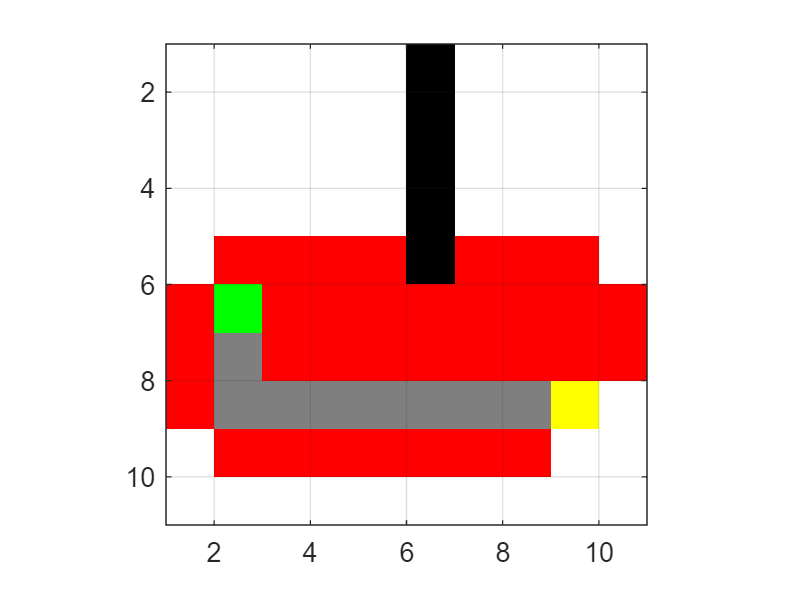

%
% TestScript for Assignment 1
%

%% Define a small map
map = false(10);

% Add an obstacle
map (1:5, 6) = true;

start_coords = [6, 2];
dest_coords  = [8, 9];

%%
close all;

[route, numExpanded] = AStarGrid (map, start_coords, dest_coords);

function [route,numExpanded] = AStarGrid (input_map, start_coords, dest_coords)
% Run A* algorithm on a grid.
% Inputs : 
%   input_map : a logical array where the freespace cells are false or 0 and
%   the obstacles are true or 1
%   start_coords and dest_coords : Coordinates of the start and end cell
%   respectively, the first entry is the row and the second the column.
% Output :
%    route : An array containing the linear indices of the cells along the
%    shortest route from start to dest or an empty array if there is no
%    route. This is a single dimensional vector
%    numExpanded: Remember to also return the total number of nodes
%    expanded during your search. Do not count the goal node as an expanded node. 

% set up color map for display
% 1 - white - clear cell
% 2 - black - obstacle
% 3 - red = visited
% 4 - blue  - on list
% 5 - green - start
% 6 - yellow - destination

cmap = [1 1 1; ...
    0 0 0; ...
    1 0 0; ...
    0 0 1; ...
    0 1 0; ...
    1 1 0; ...
    0.5 0.5 0.5];

colormap(cmap);

% variable to control if the map is being visualized on every
% iteration
drawMapEveryTime = true;

[nrows, ncols] = size(input_map);

% map - a table that keeps track of the state of each grid cell
map = zeros(nrows,ncols);

map(~input_map) = 1;   % Mark free cells
map(input_map)  = 2;   % Mark obstacle cells

% Generate linear indices of start and dest nodes
start_node = sub2ind(size(map), start_coords(1), start_coords(2));
dest_node  = sub2ind(size(map), dest_coords(1),  dest_coords(2));

map(start_node) = 5;
map(dest_node)  = 6;

% meshgrid will `replicate grid vectors' nrows and ncols to produce
% a full grid
% type `help meshgrid' in the Matlab command prompt for more information
parent = zeros(nrows,ncols);

% 
[X, Y] = meshgrid (1:ncols, 1:nrows);

xd = dest_coords(1);
yd = dest_coords(2);

% Evaluate Heuristic function, H, for each grid cell
% Manhattan distance
H = abs(X - xd) + abs(Y - yd);
H = H';
% Initialize cost arrays
f = Inf(nrows,ncols);
g = Inf(nrows,ncols);

g(start_node) = 0;
f(start_node) = H(start_node);

% keep track of the number of nodes that are expanded
numExpanded = 0;

% Main Loop

while true
    
    % Draw current map
    map(start_node) = 5;
    map(dest_node) = 6;
    
    % make drawMapEveryTime = true if you want to see how the 
    % nodes are expanded on the grid. 
    if (drawMapEveryTime)
        image(1.5, 1.5, map);
        grid on;
        axis image;
        drawnow;
    end
    
    % Find the node with the minimum f value
    [min_f, current] = min(f(:));
    
    if ((current == dest_node) || isinf(min_f))
        break;
    end;
    
    % Update input_map
    map(current) = 3;
    f(current) = Inf; % remove this node from further consideration
    
    % Compute row, column coordinates of current node
    [i, j] = ind2sub(size(f), current);
    
    % *********************************************************************
    % ALL YOUR CODE BETWEEN THESE LINES OF STARS
    % Visit all of the neighbors around the current node and update the
    % entries in the map, f, g and parent arrays
    %
    numExpanded=numExpanded+1;
    current_node=[i,j];%i是row j是col
    south_node=[i+1,j];
    north_node=[i-1,j];
    east_node=[i,j+1];
    west_node=[i,j-1];
    neighbourhood=[south_node;north_node;east_node;west_node];
    for k=1:4
        %第一组邻居开始查找确保 有邻居且没有出边界
        if( (neighbourhood(k,1)>0 && neighbourhood(k,2)>0) && (neighbourhood(k,1)<=nrows && neighbourhood(k,2)<=ncols))
            %此邻居没有被访问过，不是障碍物，也不是起点
            if( map(neighbourhood(k,1),neighbourhood(k,2)) ~=3 && map(neighbourhood(k,1),neighbourhood(k,2)) ~=2 && map(neighbourhood(k,1),neighbourhood(k,2)) ~=5)
                %距离比以前存下来的距离更近
                if(g(neighbourhood(k,1),neighbourhood(k,2))>  1+sum(abs(start_coords-current_node)) )
                    map(neighbourhood(k,1),neighbourhood(k,2))=4;%先进入现在探索列表中
                    g(neighbourhood(k,1),neighbourhood(k,2)) = 1+sum(abs(start_coords-current_node));
                    f(neighbourhood(k,1),neighbourhood(k,2))=g(neighbourhood(k,1),neighbourhood(k,2))+H(neighbourhood(k,1),neighbourhood(k,2));
                    parent(neighbourhood(k,1),neighbourhood(k,2))=sub2ind(size(map),current);%把现在的邻居点加入到父列表中
                    map(neighbourhood(k,1),neighbourhood(k,2))=3;%放入已经访问的标识符
                end
            end
        end
    end    
    
    %*********************************************************************
    
    
end

%% Construct route from start to dest by following the parent links
if (isinf(f(dest_node)))
    route = [];
else
    route = [dest_node];
    
    while (parent(route(1)) ~= 0)
        route = [parent(route(1)), route];
    end

    % Snippet of code used to visualize the map and the path
    for k = 2:length(route) - 1        
        map(route(k)) = 7;
        pause(0.1);
        image(1.5, 1.5, map);
        grid on;
        axis image;
    end
end

end
